% Main script to run Experiment 1: SIFT + SVM (Whole Image)

## Clean environment

close all;
clear variables;
clc;

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);

## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  




disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder);

    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  




disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  



## Resize image datastores and combine them with the labels

trainCDS = resizeCombineDatastore(trainingImageDS);
valCDS = resizeCombineDatastore(validationImageDS);
testCDS = resizeCombineDatastore(testImageDS);

## Show images

cellSize = [16 16]

cellSize =     16    16


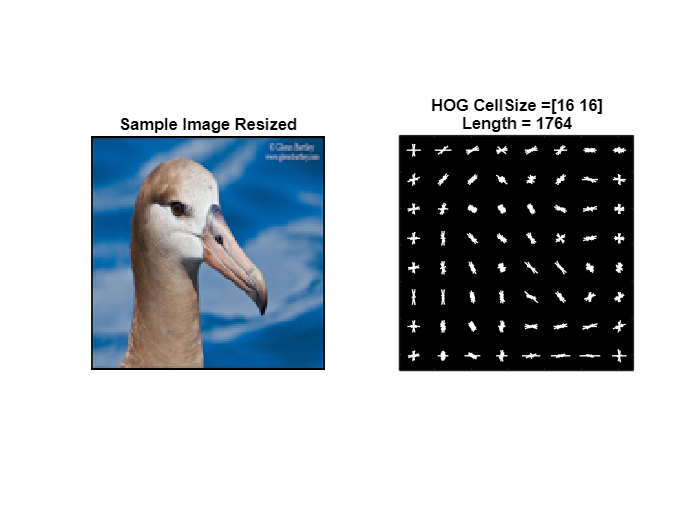

hogFeatureSize = 1764

hogFeatureSize = showImageFeatures(trainCDS, true, cellSize)

disp("HOG feature size is " + hogFeatureSize)

HOG feature size is 1764


## Extract HOG Features

trainFeatures = extractHOGFeaturesFromDatastore(trainCDS, hogFeatureSize, cellSize)

trainFeatures = 666×1764 single matrix
    0.2576    0.0277    0.0535    0.0713    0.2904    0.0615    0.0367    0.0153    0.2597    0.2192    0.0228    0.0361    0.0656    0.1756    0.2904    0.1258    0.0505    0.2904    0.0302    0.0274    0.0293    0.0253    0.2904    0.0750    0.2378    0.1860    0.0454    0.0774    0.0450    0.0642    0.0702    0.1083    0.2904    0.2904    0.2904    0.1662    0.1532    0.0112    0.0251    0.0741    0.1900    0.2507    0.0862    0.0365    0.2507    0.2507    0.0213    0.0195    0.1015    0.2507
    0.4076    0.0030    0.0086    0.0092    0.4076    0.0220    0.0260    0.0153    0.4076    0.4076    0.0011    0.0033         0    0.0158    0.0001    0.0035    0.0012    0.4076    0.0088    0.0041    0.0099    0.0057    0.4076    0.0055    0.0067    0.0032    0.0089    0.0109    0.0021    0.0063         0    0.0220         0    0.0064    0.0021    0.0109    0.3920    0.0014    0.0043    0.0131    0.1137    0.0072    0.0112    0.0036    0.3920    0.3920

testFeatures = extractHOGFeaturesFromDatastore(testCDS, hogFeatureSize, cellSize)

testFeatures = 222×1764 single matrix
    0.0412    0.0487    0.0642    0.1759    0.2575    0.1938    0.1183    0.0721    0.0652    0.1247    0.1478    0.1662    0.1928    0.2575    0.2191    0.1392    0.0973    0.0891    0.0587    0.0558    0.0871    0.2022    0.2575    0.1742    0.1188    0.0899    0.0735    0.2381    0.2575    0.2575    0.2575    0.2575    0.1689    0.1380    0.1192    0.1309    0.0986    0.1223    0.1141    0.1329    0.1884    0.1342    0.0866    0.0593    0.0609    0.0667    0.0902    0.0770    0.1423    0.2579
    0.2125    0.2277    0.2208    0.2044    0.2277    0.2277    0.2277    0.2277    0.2169    0.0462    0.0444    0.0455    0.0762    0.1800    0.1104    0.0810    0.0588    0.0435    0.2277    0.2182    0.2277    0.2110    0.2277    0.2189    0.2277    0.2076    0.2277    0.0474    0.0489    0.0557    0.0824    0.1245    0.0975    0.0615    0.0450    0.0423    0.1379    0.1100    0.1152    0.1941    0.2385    0.2385    0.2385    0.2385    0.1694    0.1202 

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Train classifier

NBClassifier = trainNBClassifier(trainFeatures, trainingImageDS.Labels);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | workers | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|===============================================================================================================|
|    1 |       5 | Best   |     0.84985 |      15.411 |     0.84985 |     0.84985 |       normal |            - |
|    2 |       5 | Accept |     0.84985 |      15.439 |     0.84985 |     0.84985 |       normal |            - |
|    3 |       5 | Accept |     0.84985 |      15.412 |     0.84985 |     0.84985 |       normal |            - |
|    4 

The error message follows:
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.
|    5 |       8 | Accept |     0.84985 |      13.116 |     0.84985 |     0.84985 |       normal |            - |
|    6 |       8 | Accept |     0.84985 |      13.267 |     0.84985 |     0.84985 |       normal |            - |
|    7 |       8 | Accept |     0.84985 |      12.719 |     0.84985 |     0.84985 |       normal |            - |
|    8 |       8 | Accept |     0.93093 |      186.69 |     0.84985 |     0.84985 |       kernel |       181.06 |
|    9 |       8 | Accept |      0.9009 |      187.73 |     0.84985 |     0.84985 |       kernel |        0.242 |
|   10 |       8 | Accept |     0.90841 |      189.04 |     0.84985 |     0.84985 |       kernel |      0.73791 |
|   11 |       8 | Best   |     0.82733 |      192.29 |     0.82733 |     0.82733 |       kernel |     0.041841 |
|   12 |       8 | Accept | 

## Evaluate

[accuracy, predictions] = evaluateClassifier(NBClassifier, testFeatures, testImageDS.Labels);

## Plot confusion matrix

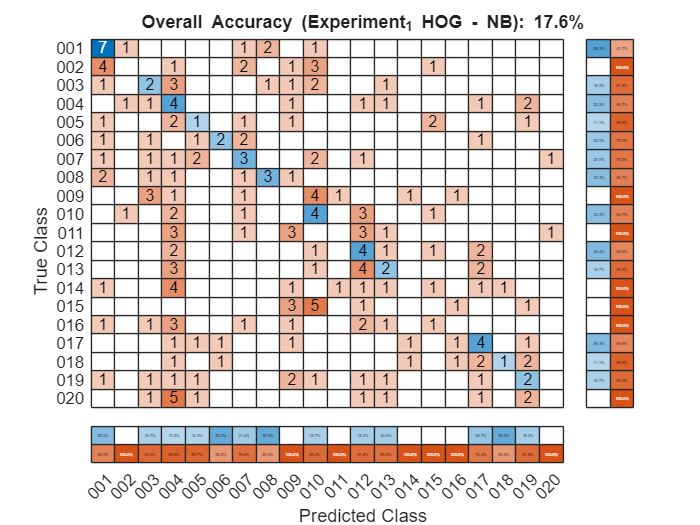

Classwise Recognition Rates:
   58.3000
         0
   18.2000
   33.3000
   11.1000
   25.0000
   25.0000
   33.3000
         0
   33.3000
         0
   36.4000
   16.7000
         0
         0
         0
   36.4000
   11.1000
   16.7000
         0



plotConfusionMatrix(testImageDS.Labels, predictions, "Overall Accuracy (Experiment_1 HOG - NB): " + string(round(accuracy*100, 1)) + "%");